clear
close all
clc

## Polse and zerros from transforfunction

G=tf([1],[1,2,1])


G =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


poles = pole(G);
zeros = zero(G);


## Is a system stabel given TF

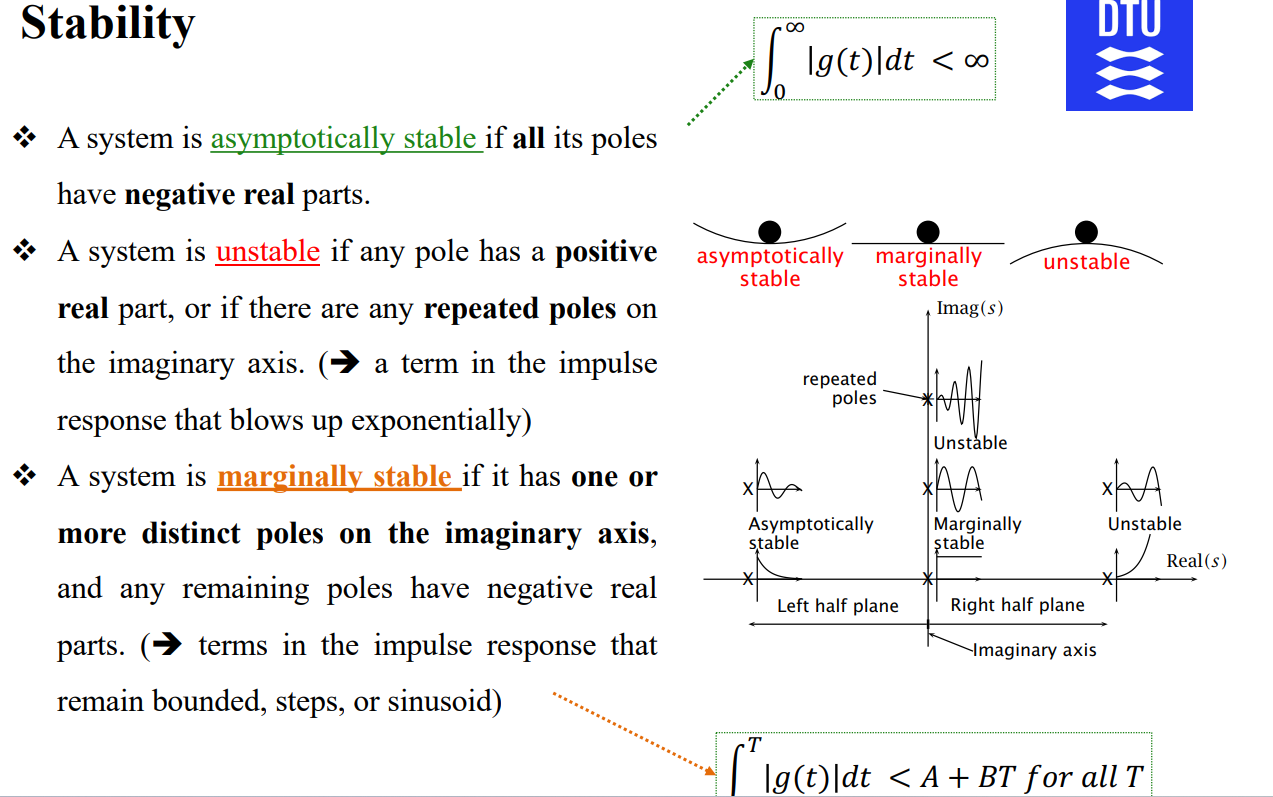

G=tf([71],[1,9,20,0,0]);

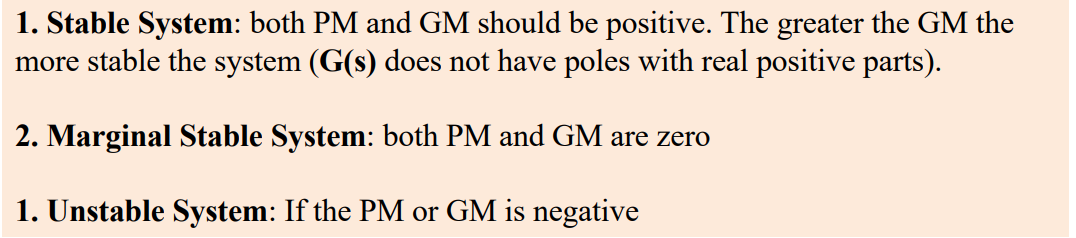

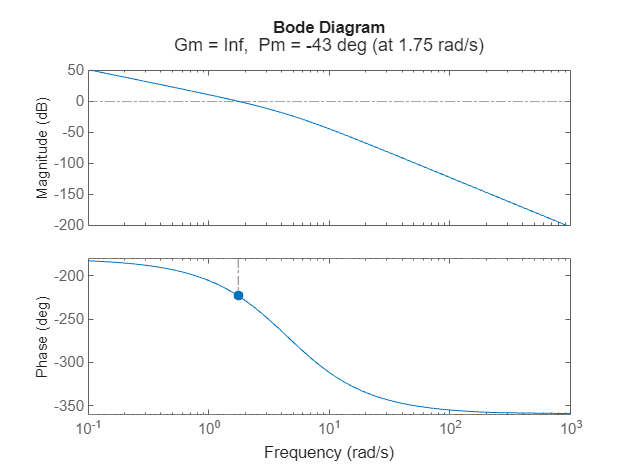

margin(G)

G=tf([101,0],[1,101,100])


G =
 
        101 s
  -----------------
  s^2 + 101 s + 100
 
Continuous-time transfer function.
Model Properties


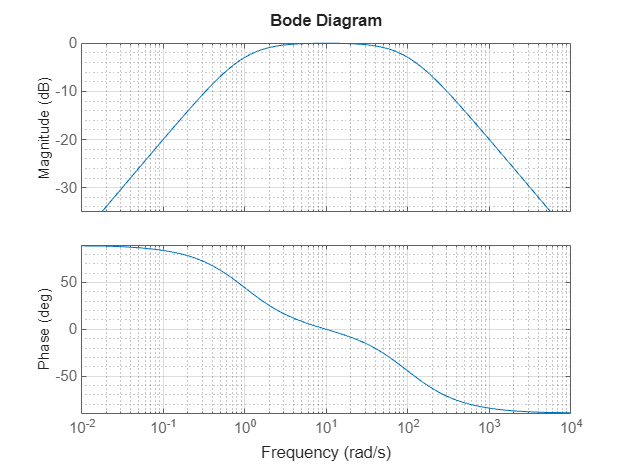

bode(G)
grid on;
grid minor 

## close vs open loop 

## 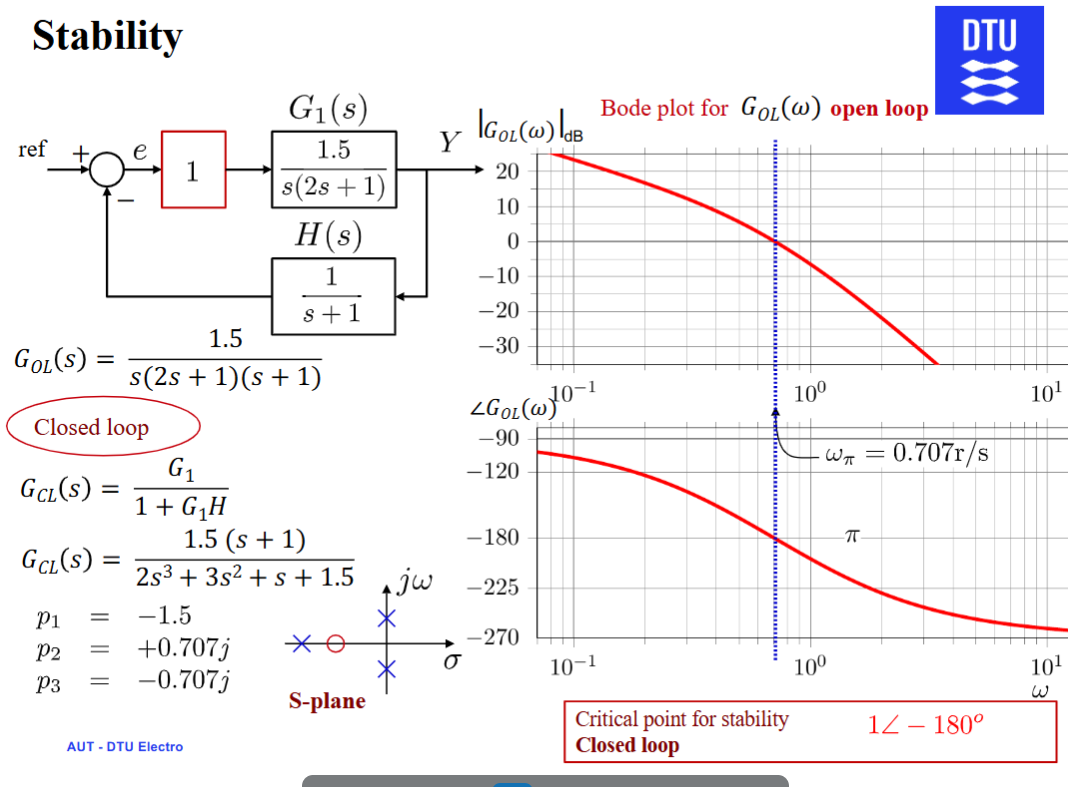 

Kp = 1;
G1=tf([1.5],[2,1,0])


G1 =
 
     1.5
  ---------
  2 s^2 + s
 
Continuous-time transfer function.
Model Properties


H1=tf([1],[1,1])


H1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


Gol = H1 * G1;
Gcl = feedback(G1,H1)


Gcl =
 
        1.5 s + 1.5
  -----------------------
  2 s^3 + 3 s^2 + s + 1.5
 
Continuous-time transfer function.
Model Properties


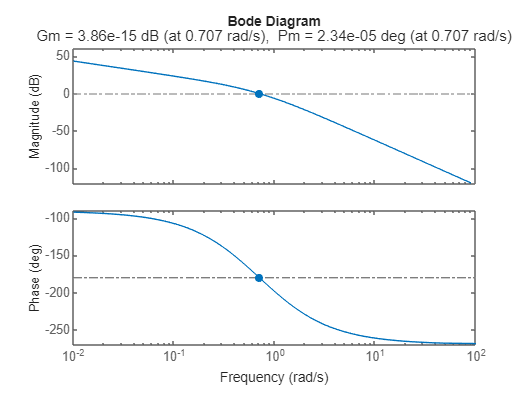

margin(Gol)

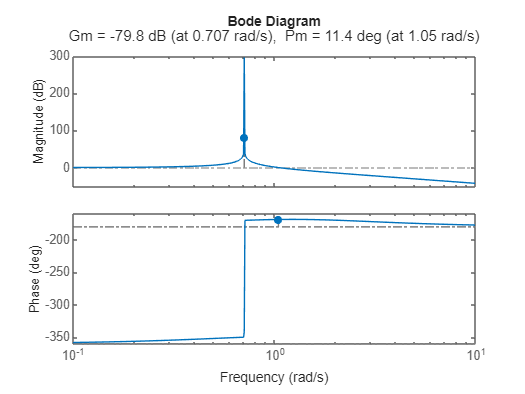

margin(Gcl)

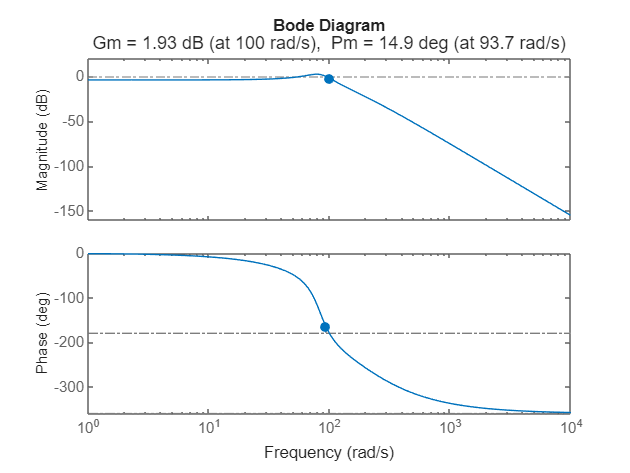

T = feedback(Gc, kp);
margin(T)